Matrix Eigenvalue Problem

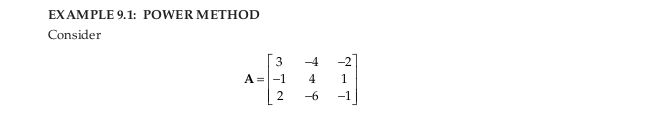

clear;clc;
A = [3 -4 -2;-1 4 1;2 -6 -1];
[e_val, e_vec, k] = PowerMethod(A) % Default x1 and tol

e_val =    3.000187984967858


e_vec =   -0.408299451129388
   0.408238057631639
  -0.816476115087629


k =     20


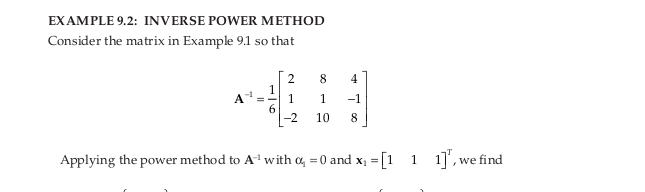

clear;clc;
A = [3 -4 -2;-1 4 1;2 -6 -1]; Ai = inv(A);
[e_val, e_vec, k] = PowerMethod(Ai)

e_val =    0.999922376185725


e_vec =    0.707049681304207
  -0.000056652962291
   0.707163874189046


k =     12


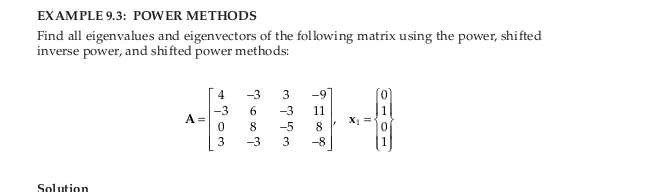

clear;clc;
A = [4 -3 3 -9;-3 6 -3 11;0 8 -5 8;3 -3 3 -8];
x1 = [0;1;0;1]; % Initial vector
[e_val, e_vec] = PowerMethod(A, x1) % Default values for tol and kmax

e_val =   -4.999968410791076


e_vec =    0.500001184596738
  -0.499998815400456
  -0.499998815400455
   0.500001184596738



[e_val, e_vec] = ShiftInvPower(A, 0, x1)

e_val =    1.000122264934998


e_vec =   -0.816455785971494
   0.408351288992079
   0.000122350940251
  -0.408226847919665



[e_val, e_vec] = ShiftInvPower(A, -1.5, x1) % alpha=−1.5

e_val =   -1.999996702852188


e_vec =   -0.577350586438320
   0.577350110565224
  -0.000000000039305
  -0.577350110565203



A1 = A + 2*eye(4,4);
[e_val, e_vec] = PowerMethod(A1, x1)

e_val =    4.999975834204658


e_vec =   -0.000000000000000
   0.707107082735482
   0.707106479637227
   0.000000603098255


buit-in function

A = [4 -3 3 -9;-3 6 -3 11;0 8 -5 8;3 -3 3 -8];
[V,D] = eig(A)

V =    0.816496580927726   0.577350269189626  -0.000000000000001   0.500000000000000
  -0.408248290463863  -0.577350269189626  -0.707106781186547  -0.500000000000000
                   0                   0  -0.707106781186548  -0.500000000000000
   0.408248290463863   0.577350269189626  -0.000000000000000   0.500000000000000


D =    1.000000000000000                   0                   0                   0
                   0  -2.000000000000000                   0                   0
                   0                   0   2.999999999999997                   0
                   0                   0                   0  -4.999999999999999


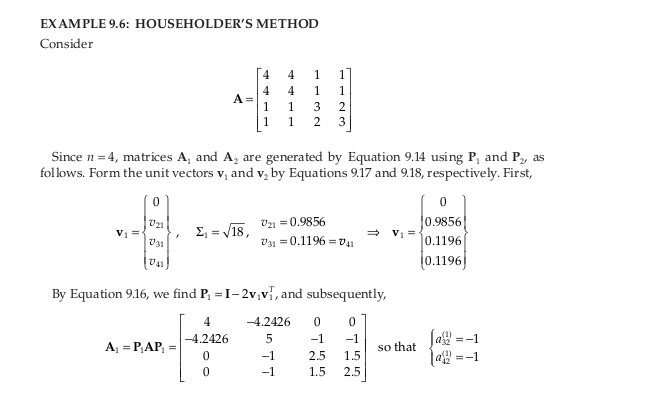

clear;clc;
A = [4 4 1 1;4 4 1 1;1 1 3 2;1 1 2 3];
T = Householder(A)

T =    4.000000000000000  -4.242640687119286   0.000000000000000   0.000000000000000
  -4.242640687119284   4.999999999999999   1.414213562373094                   0
                   0   1.414213562373096   4.000000000000000   0.000000000000000
                   0   0.000000000000000   0.000000000000000   1.000000000000000


A = [4 4 1 1;4 4 1 1;1 1 3 2;1 1 2 3];
[T, Tfinal, e_vals, m] = HouseholderQR(A)

T =    4.000000000000000  -4.242640687119286   0.000000000000000   0.000000000000000
  -4.242640687119284   4.999999999999999   1.414213562373094                   0
                   0   1.414213562373096   4.000000000000000   0.000000000000000
                   0   0.000000000000000   0.000000000000000   1.000000000000000


Tfinal =    8.999985332588196  -0.008563693355437  -0.000000000000000  -0.000000000000002
  -0.008563693355437   4.000014667411804  -0.000000000000000   0.000000000000001
                   0   0.000000000000000   1.000000000000000  -0.000000000000000
                   0  -0.000000000000000   0.000000000000000   0.000000000000000


e_vals =    8.999985332588196
   4.000014667411804
   1.000000000000000
   0.000000000000000


m =      7


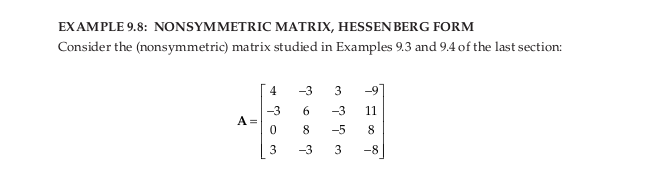

clear;clc;
A = [4 -3 3 -9;-3 6 -3 11;0 8 -5 8;3 -3 3 -8];
[H, Hfinal, e_vals, m] = HouseholderQR(A);

[H, Hfinal, e_vals, m] = HouseholderQR(A, [], 60)

H =    4.000000000000000  -4.242640687119286  -0.852444478725890  -8.959538961949423
   4.242640687119285  -5.000000000000001  -0.720467292911551 -14.610986512889697
   0.000000000000000  -0.000000000000001  -1.867362706121233 -12.530549175515068
  -0.000000000000000   0.000000000000000  -1.216840676530308  -0.132637293878766


Hfinal =   -4.999966278883894   5.196165912675970 -13.472172979209112  16.263474485634607
   0.000019468625733  -2.000032152111458   3.535623548366870   2.857631984294000
   0.000000000006953   0.000002218892673   2.999998433302996  -1.154701802567472
   0.000000000000000   0.000000000000004   0.000000003996958   0.999999997692351


e_vals =   -4.999966278883894
  -2.000032152111458
   2.999998433302996
   0.999999997692351


m =     52
